# Goal:  Transmission Function (TF) Covariance Matrix

# Read TF Lookup Table

# Thierry Lasserre

# Last Updated: March 21 2018

## Produce Lookup Tables with 

- IS Probabilities

- Transfer Functions

- uncomment the first time you use it to produce files%

%z=ref_tfcm();z.ComputeTFCovMatrix('Ntrials',1000);

## Read File 

Example of content

             TFf: [66×10000×105 double] - Transfer Functions

                  qU    : 66, Flat60 TD

                 Trials : 10 0000

                  Te    : 105, from -5 to 100 eV 

            TF_CovMat: [66×105×105 double] - Covariance Matrices

            Nbx Cov Mat  : 66, 1 per qU

            Cov Mat Size : 105 x 105 (nTe x nTe)


%f=importdata('IS-LookupTable-Trials-1000-2.5e+17-molPercm2-NIS-11.mat');
f=importdata('testCM.mat');
%f=importdata('tf100-KATRINnominal.mat');
f.obj.DisplayWGTSMACEInfo();

--------------------------------------------------------------
KATRIN WGTS and MACE with following properties:
--------------------------------------------------------------
- - - - - WGTS 
   - Radius Flux Tube in cm: 4.1 
   - Column Density in molecules/cm^2: 2.5e+17 
   - Temparature in K: 0.99 
   - Bs in Tesla: 2.52 +- 0.0252 
   - Cos Maximum Acceptance Angle 0.63057 
- - - - - Isotropologues 
   - T-T purity: 0.99 
   - D/H: 1 
   - H-T fraction in WGTS: 0 
   - D-T fraction in WGTS: 0.01 
   - H-D fraction in WGTS 0 
- - - - - Scattering Probabilities (from no-scattering) 
63.4723      27.8596      9.06871      2.34073     0.501508    0.0920982    0.0148367   0.00213317  0.000277349  3.29456e-05  3.60491e-06
- - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - 
- - - - - MACE 
   - B pinch in Tesla: 4.2 +- 0.042 
   - B analysis plane in Tesla: 0.0006 +- 6e-06 
- - - - - Analysis Plane 
   - MACE_Ba_Setting: 2.7G 
   - Analysis Plane B-field Correction, Tesla: 
0  0  

## Initialization - Pickup ONE qU bin

Computation is done for ALL qU, independently

For simplicity we plot only 1 qU realization

% Ntrials
Ntrials = 1000;
% Fix qU bin
qu        = 10;
% Decode
TfqU      = squeeze(f.TFf(qu,:,:))'; TfqU=TfqU';
TfqUmean  = mean(TfqU,1);

## Plot all TF's

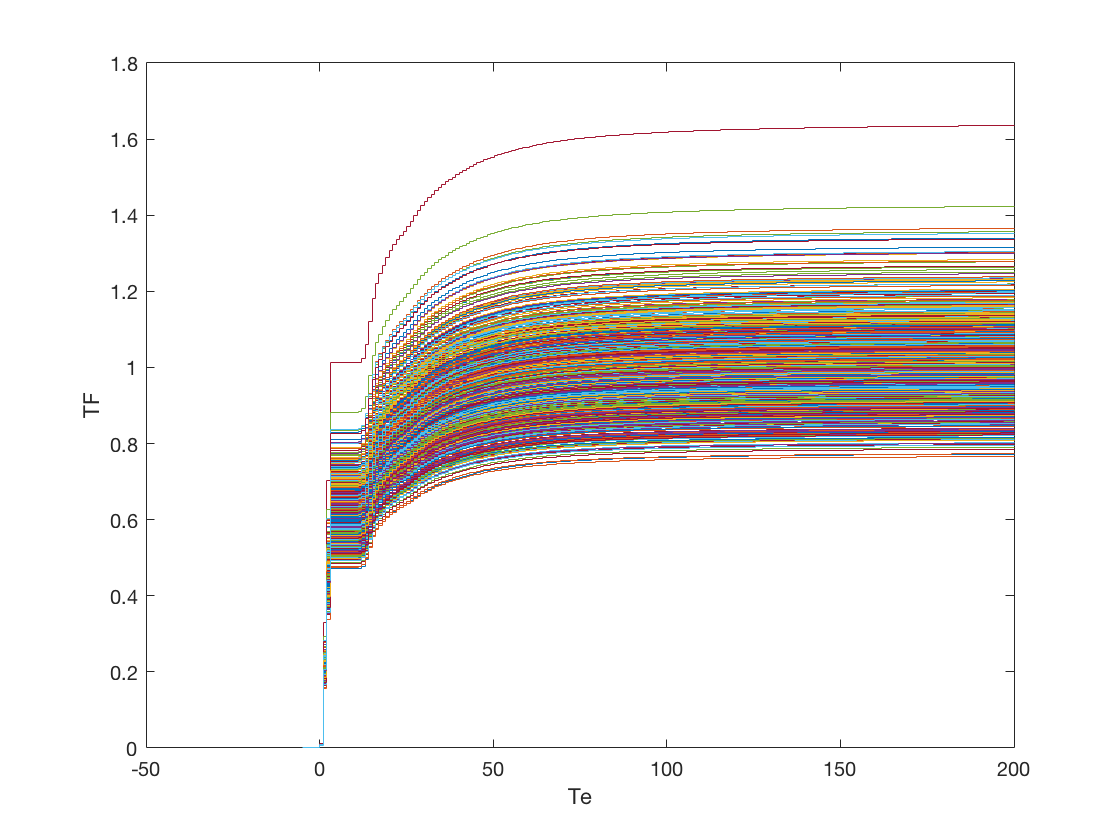

tfs = TfqU';
stairs(f.ElossSave,tfs)
xlabel('Te');
ylabel('TF' )

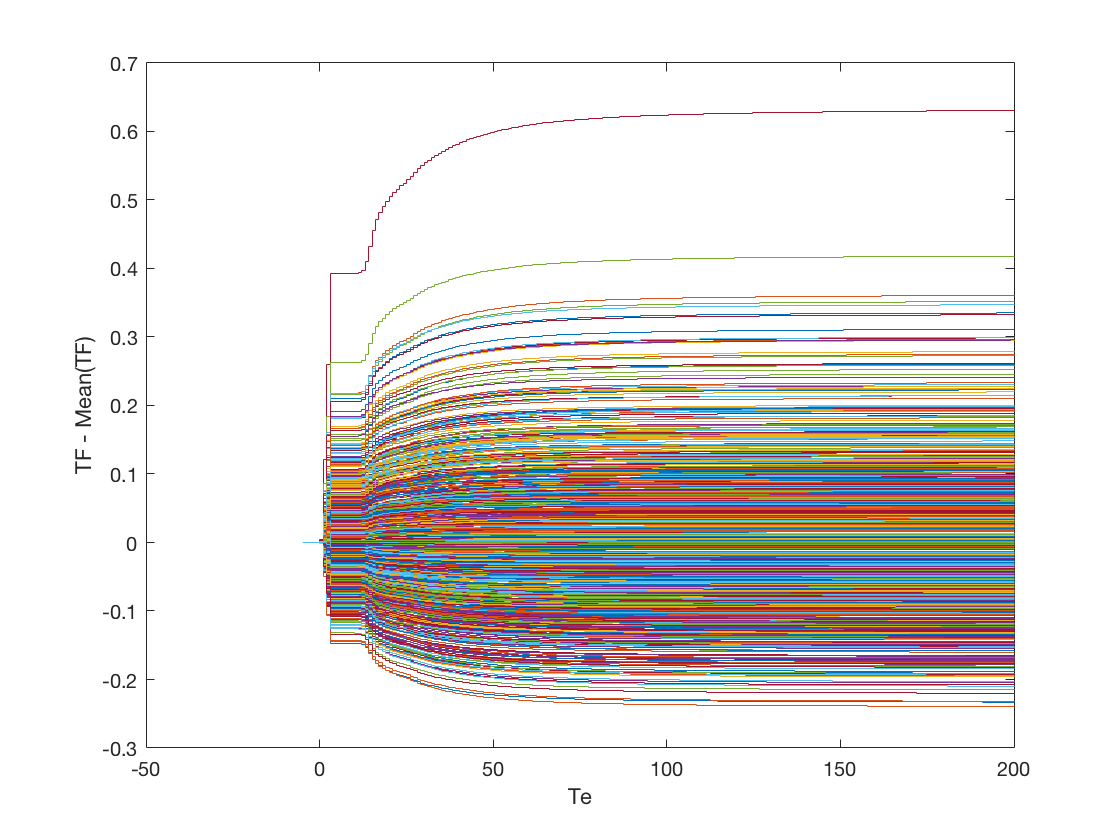


stairs(f.ElossSave,tfs-TfqUmean')
xlabel('Te');
ylabel('TF - Mean(TF)')

## Plot Covariance Matrix

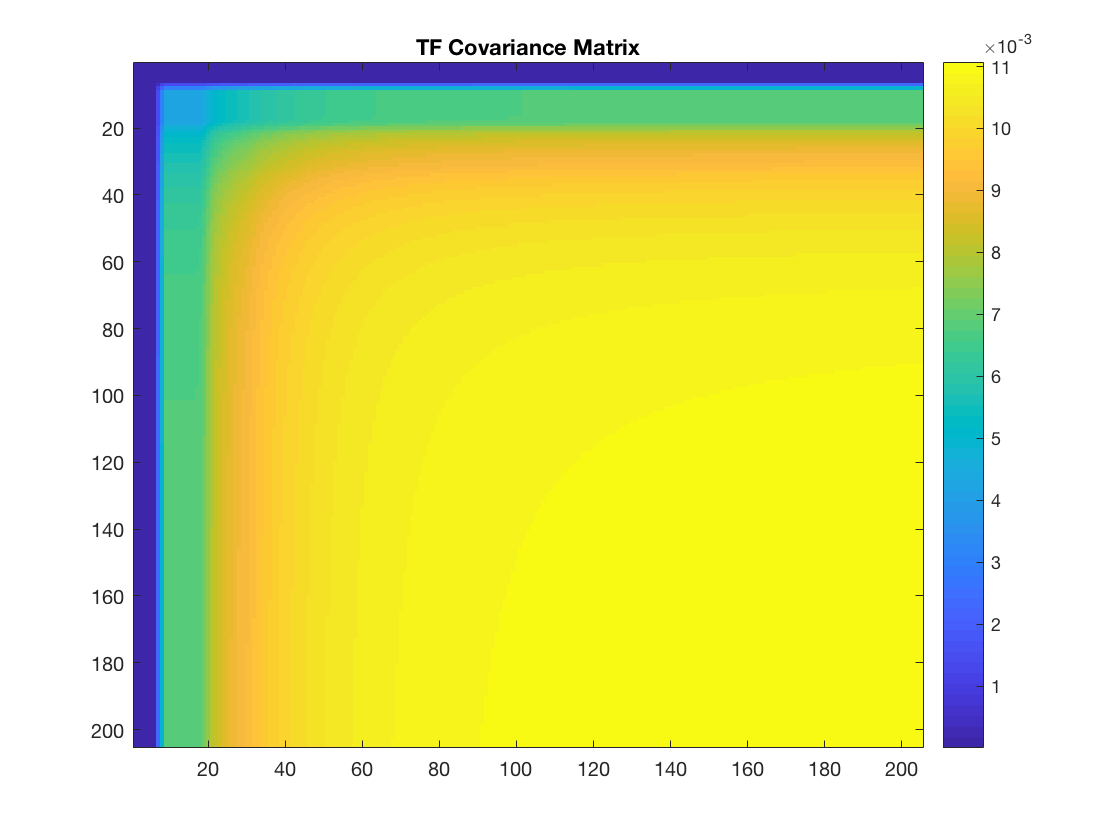

CovMat = squeeze(f.TF_CovMat(qu,:,:));
imagesc(CovMat);
colorbar;
title('TF Covariance Matrix')

## Plot Correlation Matrix

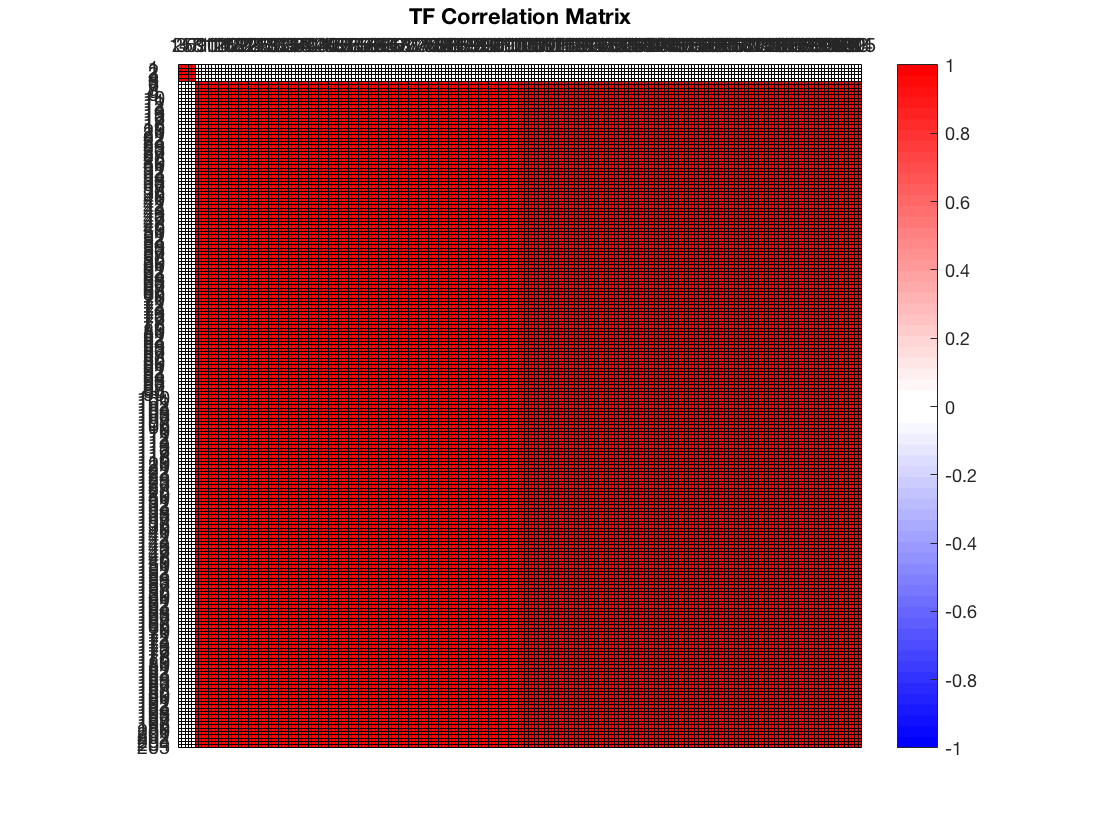

corplot(CovMat);
title('TF Correlation Matrix')
colorbar;

## Plot Mean TF and Diagonal Element Uncertainties

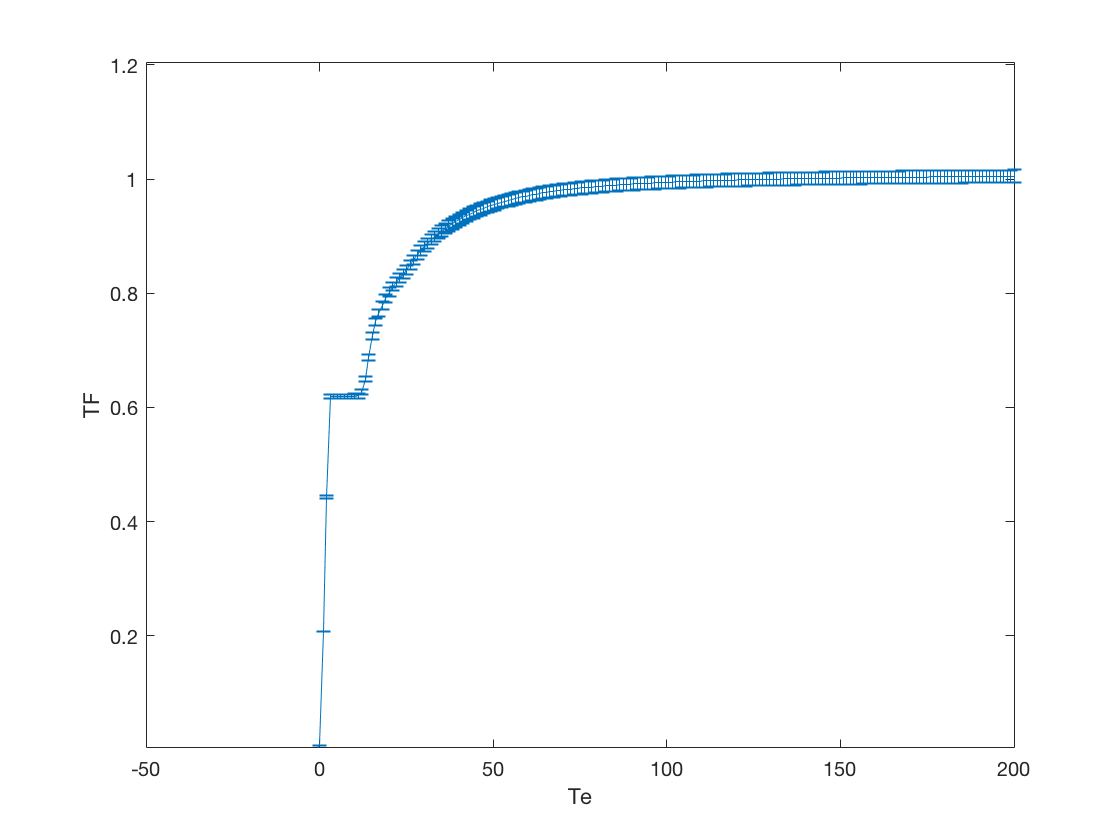

TfqUmean=TfqUmean+1e-9; % avoid division by zero
errorbar(f.ElossSave,TfqUmean,diag(CovMat));
xlabel('Te');
ylabel('TF' )

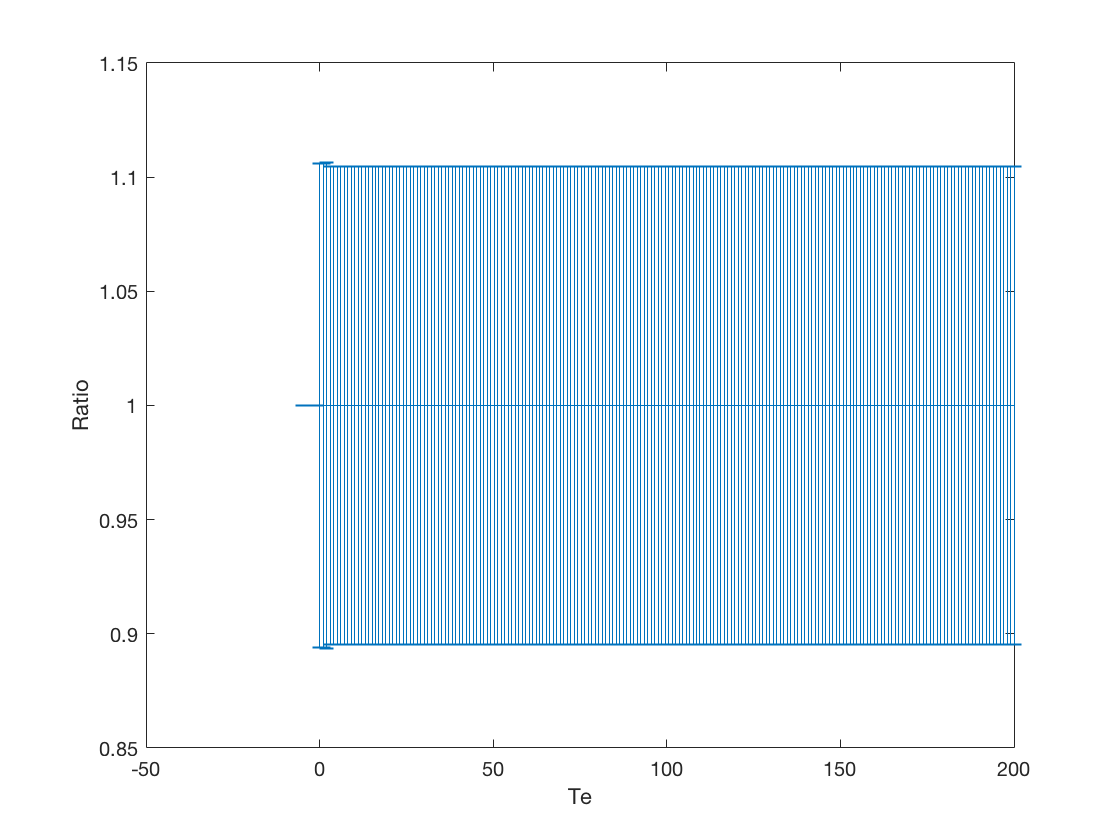

errorbar(f.ElossSave,TfqUmean./TfqUmean,sqrt(diag(CovMat))./TfqUmean');
xlabel('Te');
ylabel('Ratio' )